disp('linear regression for poly 2 degree ');

linear regression for poly 2 degree 


% poly 2 degree 
% y= a0 + a1*x + a2*x^2
x = [0 1 2 3 4 5] ; 
y = [2.1 7.7 13.6 27.2 40.9 61.1];

% ∑ y     = n*a0 + a1*∑x + a2*∑x^2
% ∑ yx    = a0∑x + a1*∑x^2 + a2*∑x^3
% ∑ y*x^2 = a0∑x^2 + a1*∑x^3 + a2*∑x^4
% get variable values

n    = length(x) ;
sx   = sum(x);
sy   = sum(y);
sxy  = sum(x.*y);
sx2y = sum((x.^2).*y);
sx2 = sum(x.^2);
sx3 = sum(x.^3);
sx4 = sum(x.^4);

% we split this 3 equations into two matrices
Rightcoef = [ n sx sx2 ; sx sx2 sx3 ; sx2 sx3 sx4] ;
Leftcoef = [sy ; sxy ; sx2y] ;
%solve as matrices
%think of it as 
%Leftcoef = Rightcoef  * sol
sol  = Rightcoef \ Leftcoef ;   % as same as 'sol  = Rightcoef^-1 * Leftcoef' but the backslash expression is more effcint for more info : https://www.mathworks.com/help/matlab/ref/mldivide.html

a0 = sol(1) ;
a1 = sol(2) ;
a2 = sol(3) ;


%calc R^2
yav = mean(y) ;
st = sum( (y-yav).^2 )  ;
sr = sum((y-a0-a1*x-a2*x.^2).^2) ;
r2=(st-sr)/st ;

disp('a0');disp(a0) ;

a0
    2.4786



disp('a1');disp(a1) ;

a1
    2.3593



disp('a2');disp(a2) ;

a2
    1.8607



disp('r^2 ');disp(r2) ;

r^2 
    0.9985



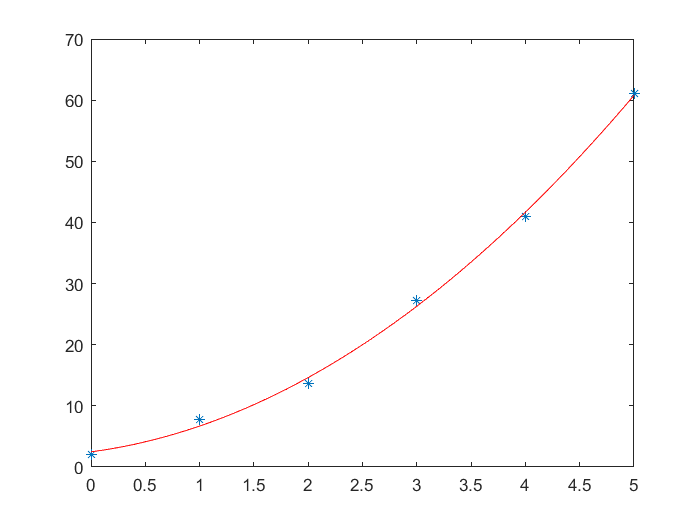


x1 = min(x):0.1:max(x) ;
%y= a0 + a1*x + a2*x^2
y1 = a0 + a1*x1 + a2*x1.^2 ;

plot(x,y ,'*' , x1 ,y1 ,'r-')